T0 = eye(4,4)

T0 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


T1 = transl(1,2,3)*rpy2tr(0.6, 0.8, 1.4, 'xyz') 

T1 =     0.5750   -0.3934    0.7174    1.0000
    0.6794   -0.2589   -0.6866    2.0000
    0.4558    0.8822    0.1184    3.0000
         0         0         0    1.0000


% the default corresponds to rotations about the Z, Y, X axes
% respectively

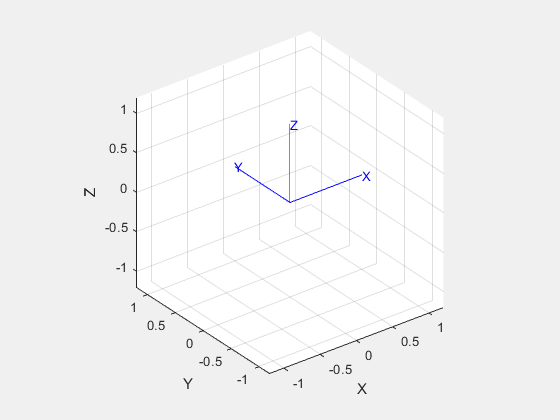

trplot(T0)

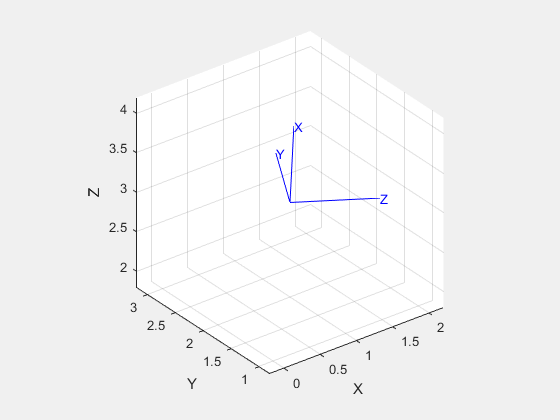

trplot(T1)

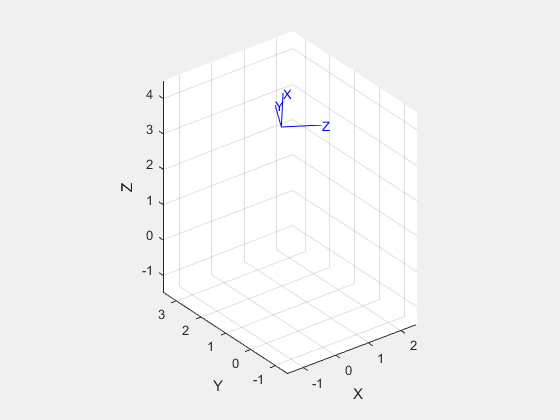

tranimate(T0,T1)

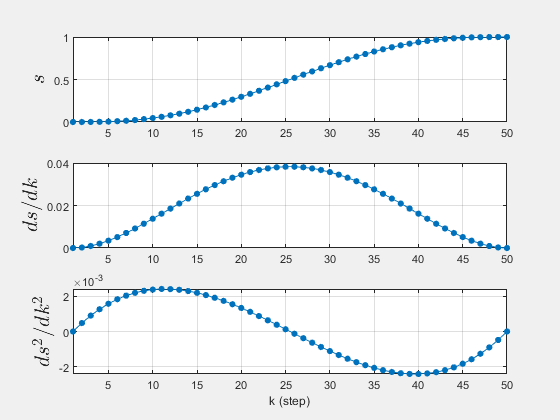

tpoly(0, 1, 50) %initial s, final s, time steps (graph)

s = tpoly(0, 1, 50) %vector s

s =          0
    0.0001
    0.0006
    0.0021
    0.0048
    0.0091
    0.0152
    0.0233
    0.0336
    0.0461


[s, sd, sdd] = tpoly(0, 1, 50) %vectors s, sd, sdd

s =          0
    0.0001
    0.0006
    0.0021
    0.0048
    0.0091
    0.0152
    0.0233
    0.0336
    0.0461


sd =          0
    0.0002
    0.0009
    0.0020
    0.0034
    0.0051
    0.0071
    0.0092
    0.0114
    0.0138


sdd =          0
    0.0005
    0.0009
    0.0013
    0.0016
    0.0018
    0.0020
    0.0022
    0.0023
    0.0024


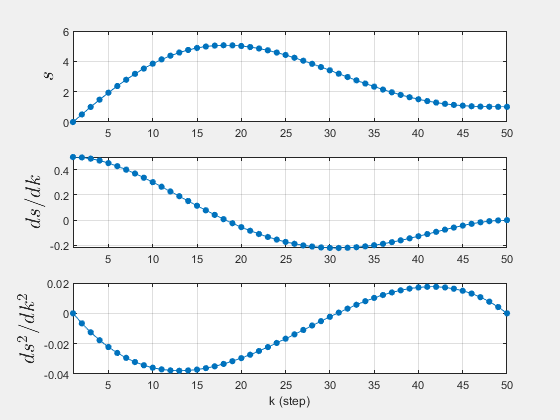

tpoly(0, 1, 50, 0.5, 0) %initial s, final s, time steps, initial v, final v

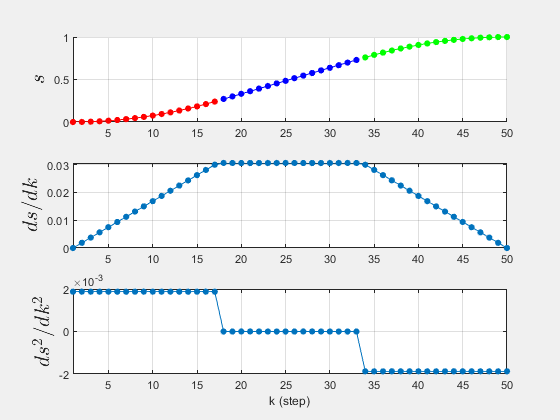

lspb(0, 1, 50)

s = lspb(0, 1, 50)

s =          0
    0.0009
    0.0037
    0.0084
    0.0150
    0.0234
    0.0337
    0.0459
    0.0600
    0.0759


[s, sd, sdd] = lspb(0, 1, 50)

s =          0
    0.0009
    0.0037
    0.0084
    0.0150
    0.0234
    0.0337
    0.0459
    0.0600
    0.0759


sd =          0
    0.0019
    0.0037
    0.0056
    0.0075
    0.0094
    0.0112
    0.0131
    0.0150
    0.0169


sdd =     0.0019
    0.0019
    0.0019
    0.0019
    0.0019
    0.0019
    0.0019
    0.0019
    0.0019
    0.0019


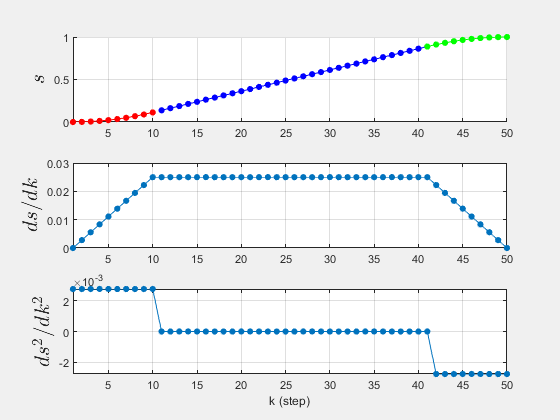

lspb(0, 1, 50, 0.025)

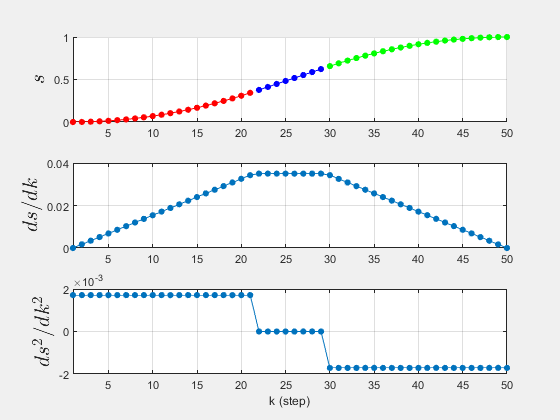

lspb(0, 1, 50, 0.035)

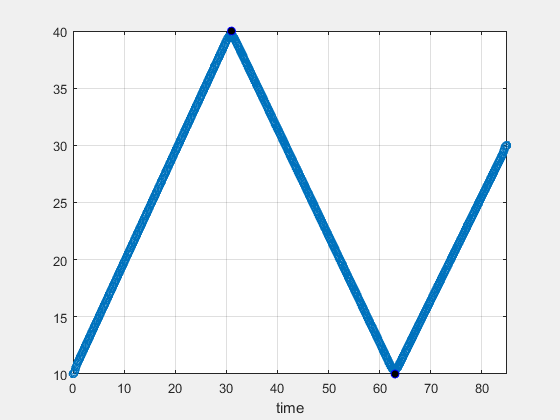

mstraj([40;10;30], 1, [], 10, 0.1, 2)

% first point: 10,  last point: 30
% via points: 40,10
% velocity is 1 unit per sec
% time interval = 0.1
% t_acc (acceleration time) = 2

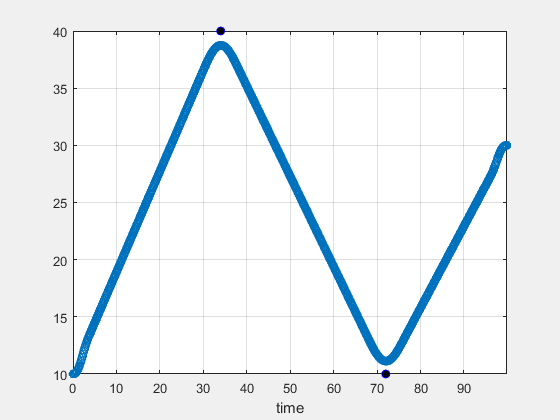

mstraj([40;10;30], 1, [], 10, 0.1, 8)

% smooth but misses the point

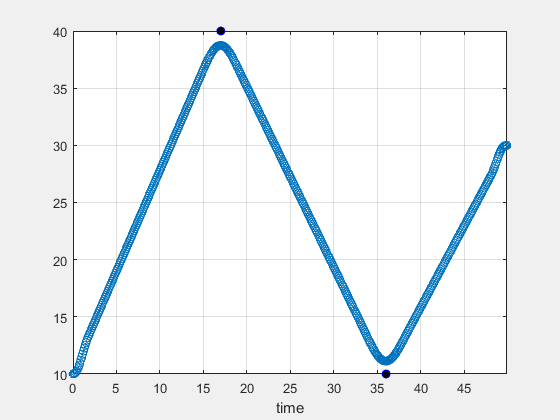

mstraj([40;10;30], 2, [], 10, 0.1, 4)

% double the speed

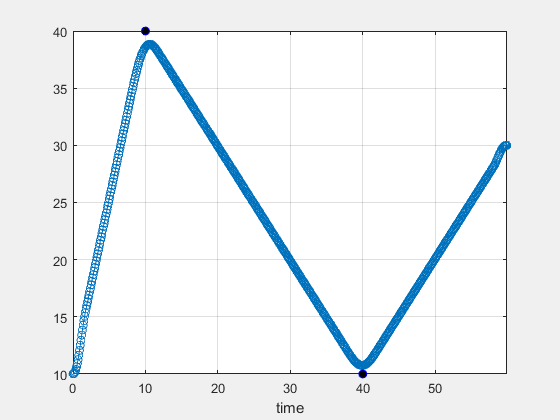

mstraj([40;10;30], [], [10 30 20], 10, 0.1, 4)

% first segment lasts for 10 seconds
% second segment lasts for 30 seconds
% third segment lasts for 20 seconds

first = [10 20]

first =     10    20


last = [30 10]

last =     30    10


x = jtraj(first, last, 50)

x =    10.0000   20.0000
   10.0016   19.9992
   10.0128   19.9936
   10.0418   19.9791
   10.0959   19.9520
   10.1813   19.9094
   10.3031   19.8485
   10.4653   19.7674
   10.6712   19.6644
   10.9229   19.5385


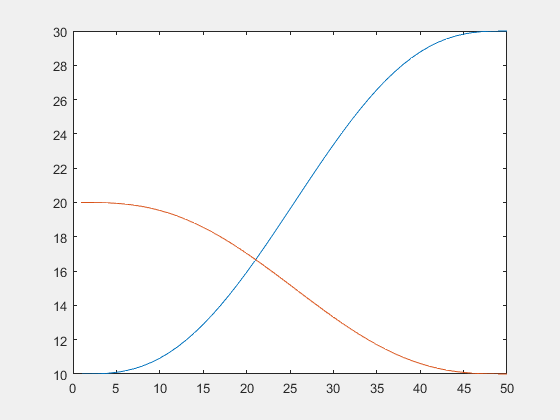

% [10 20] is the first point
% [30 10] is the last point
plot(x)

[x, xd] = jtraj(first, last, 50)

x =    10.0000   20.0000
   10.0016   19.9992
   10.0128   19.9936
   10.0418   19.9791
   10.0959   19.9520
   10.1813   19.9094
   10.3031   19.8485
   10.4653   19.7674
   10.6712   19.6644
   10.9229   19.5385


xd =          0         0
    0.2398   -0.1199
    0.9197   -0.4598
    1.9821   -0.9910
    3.3722   -1.6861
    5.0375   -2.5187
    6.9280   -3.4640
    8.9963   -4.4981
   11.1973   -5.5987
   13.4888   -6.7444


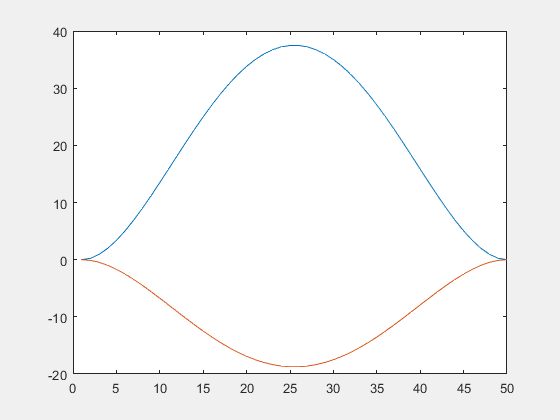

plot(xd)

v_initial = [0 0]

v_initial =      0     0


v_final = [10 10]

v_final =     10    10


[x, xd] = jtraj(first, last, 50, v_initial, v_final)

x =    10.0000   20.0000
   10.0013   19.9988
   10.0103   19.9911
   10.0336   19.9709
   10.0772   19.9333
   10.1461   19.8741
   10.2445   19.7899
   10.3760   19.6781
   10.5433   19.5366
   10.7485   19.3641


xd =          0         0
    0.1922   -0.1675
    0.7384   -0.6411
    1.5944   -1.3787
    2.7182   -2.3401
    4.0692   -3.4870
    5.6091   -4.7829
    7.3011   -6.1933
    9.1106   -7.6854
   11.0047   -9.2284


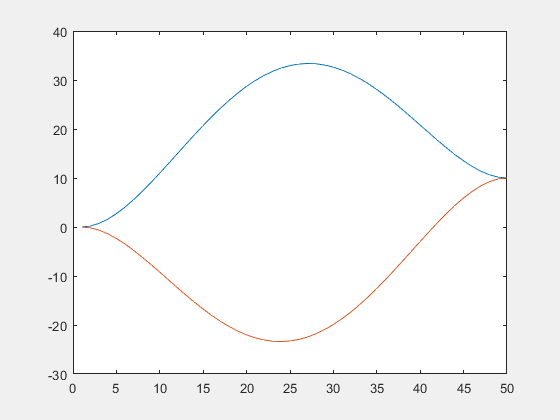

plot(xd)

% 3d example
start = [40 50]

start =     40    50


via = [60 30; 40 10; 20 30; start]

via =     60    30
    40    10
    20    30
    40    50


x = mstraj(via, 2, [], start, 0.1, 1)

x =    40.0344   49.9656
   40.1999   49.8001
   40.4690   49.5310
   40.7412   49.2588
   40.9524   49.0476
   41.1429   48.8571
   41.3333   48.6667
   41.5238   48.4762
   41.7143   48.2857
   41.9048   48.0952


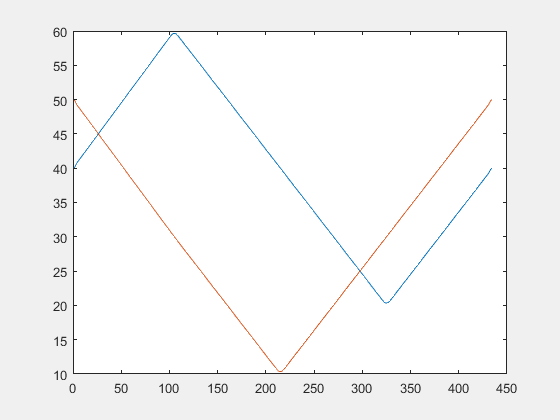

plot(x) %plot traj vs time

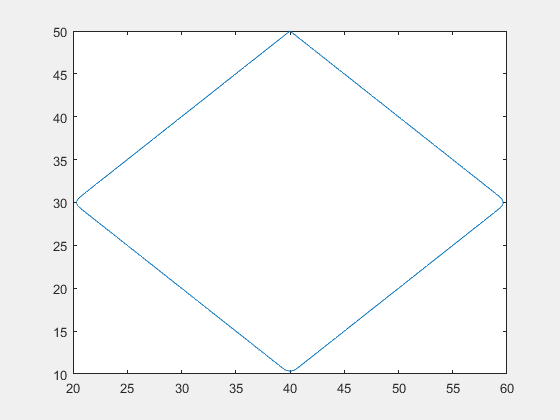

plot(x(:,1), x(:,2)) %plot p1 vs p2

v_x = 1 %v in x axis

v_x = 1

v_y = 3 %v in y axis

v_y = 3

x = mstraj(via, [v_x v_y], [], start, 0.1, 1)

x =    40.0176   49.9824
   40.1024   49.8976
   40.2402   49.7598
   40.3796   49.6204
   40.4878   49.5122
   40.5854   49.4146
   40.6829   49.3171
   40.7805   49.2195
   40.8780   49.1220
   40.9756   49.0244


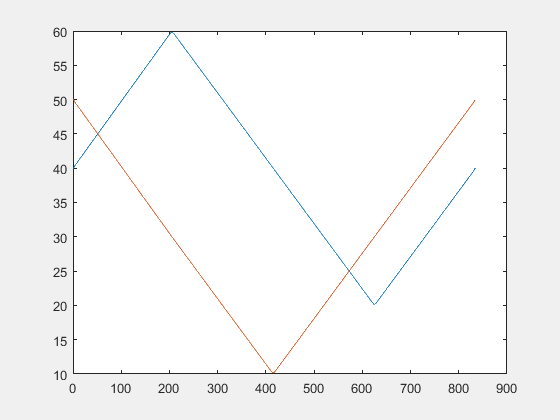

plot(x) 

%takes twice as long because slowest axis (x axis)
% is half the speed

rpy_initial = [0 0 0]

rpy_initial =      0     0     0


rpy_final = [-pi/2 pi/2 pi/4]

rpy_final =    -1.5708    1.5708    0.7854


x = jtraj(rpy_initial, rpy_final, 100) %100 time steps

x =          0         0         0
   -0.0000    0.0000    0.0000
   -0.0001    0.0001    0.0001
   -0.0004    0.0004    0.0002
   -0.0010    0.0010    0.0005
   -0.0019    0.0019    0.0009
   -0.0032    0.0032    0.0016
   -0.0050    0.0050    0.0025
   -0.0073    0.0073    0.0037
   -0.0103    0.0103    0.0051


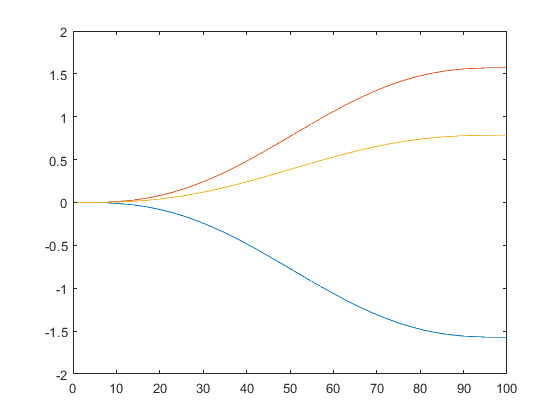

plot(x)

R = rpy2r(x, 'xyz') %convert each row into rotation matrix

R = R(:,:,1) =

     1     0     0
     0     1     0
     0     0     1


R(:,:,2) =

    1.0000    0.0000    0.0000
   -0.0000    1.0000   -0.0000
   -0.0000    0.0000    1.0000


R(:,:,3) =

    1.0000    0.0001    0.0001
   -0.0001    1.0000   -0.0001
   -0.0001    0.0001    1.0000


R(:,:,4) =

    1.0000    0.0004    0.0004
   -0.0004    1.0000   -0.0002
   -0.0004    0.0002    1.0000


R(:,:,5) =

    1.0000    0.0010    0.0010
   -0.0010    1.0000   -0.0005
   -0.0010    0.0005    1.0000


R(:,:,6) =

    1.0000    0.0019    0.0019
   -0.0019    1.0000   -0.0009
   -0.0019    0.0009    1.0000


R(:,:,7) =

    1.0000    0.0032    0.0032
   -0.0032    1.0000   -0.0016
   -0.0032    0.0016    1.0000


R(:,:,8) =

    1.0000    0.0050    0.0050
   -0.0050    1.0000   -0.0025
   -0.0050    0.0025    1.0000


R(:,:,9) =

    0.9999    0.0073    0.0073
   -0.0073    1.0000   -0.0037
   -0.0073    0.0036    1.0000


R(:,:,10) =

    0.9999    0.0103    0.0103
   -0.0102    0.9999   -0

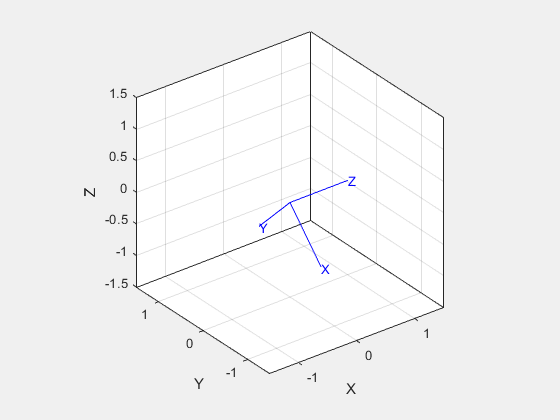

tranimate(R)

q1 = UnitQuaternion

 
q1 = 
 
1 < 0, 0, 0 >
 


q2 = UnitQuaternion( rotx(pi/2) )

 
q2 = 
 
0.70711 < 0.70711, 0, 0 >
 


initial = q1.interp(q2, 0)

 
initial = 
 
1 < 0, 0, 0 >
 


final = q1.interp(q2, 1)

 
final = 
 
0.70711 < 0.70711, 0, 0 >
 


halfway = q1.interp(q2, 0.5)

 
halfway = 
 
0.92388 < 0.38268, 0, 0 >
 


T = ctraj(T0, T1, 50) %cardician trajectory of 50 time steps

T = T(:,:,1) =

     1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


T(:,:,2) =

    1.0000   -0.0010    0.0002    0.0009
    0.0010    1.0000   -0.0014    0.0019
   -0.0002    0.0014    1.0000    0.0028
         0         0         0    1.0000


T(:,:,3) =

    1.0000   -0.0039    0.0010    0.0037
    0.0039    1.0000   -0.0057    0.0075
   -0.0009    0.0057    1.0000    0.0112
         0         0         0    1.0000


T(:,:,4) =

    1.0000   -0.0087    0.0022    0.0084
    0.0088    0.9999   -0.0128    0.0169
   -0.0021    0.0128    0.9999    0.0253
         0         0         0    1.0000


T(:,:,5) =

    0.9999   -0.0155    0.0040    0.0150
    0.0156    0.9996   -0.0227    0.0300
   -0.0036    0.0228    0.9997    0.0450
         0         0         0    1.0000


T(:,:,6) =

    0.9997   -0.0242    0.0064    0.0234
    0.0244    0.9991   -0.0355    0.0469
   -0.0055    0.0356    0.9993    0.0703
         0         0         0    1

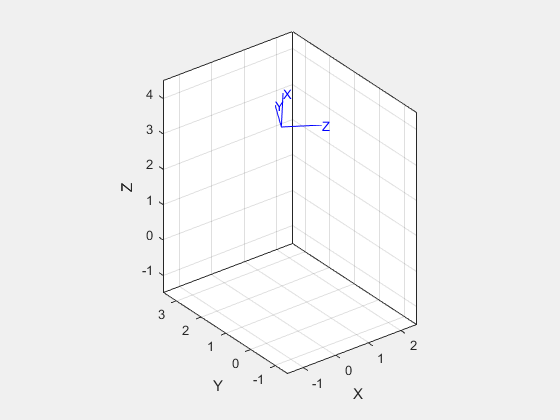

tranimate(T)